# Examen Final

Robot Péndulo 1 GDL

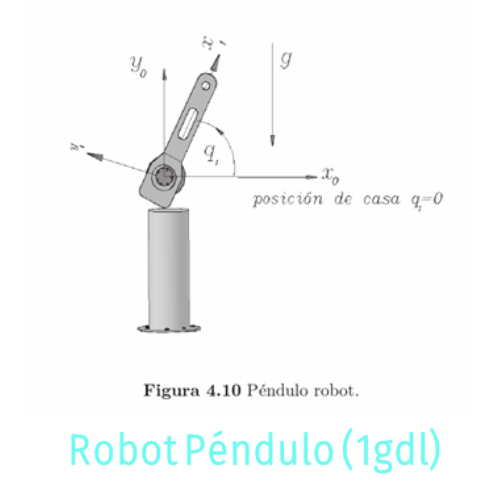

- Se comienza con una limpieza de pantalla y del workspace para un trabajo mucho mas eficiente, asi como tambien se inicializa el temporizador del programa.

%Limpieza de pantalla
clear all
close all
clc

%Temporizador
tic

- En esta parte se declaran las variables simbolicas para los angulos de cada articulacion, para las velocidades y aceleraciones de las articulaciones, para las masas y matrices de inercia, para las longitudes de los eslabones, las distancias al centro de masa de cada eslabon y las variables definidas de pi, la gravedad, aceleracion y cero.

%Declaración de variables simbólicas

%Angulos de cada articulación
syms th1(t) t  
%Velocidades de cada articulación
syms th1p(t) 
%Aceleraciones de cada articulación
syms th1pp(t) 
%Masas y matrices de Inercia
syms m1 Ixx1 Iyy1 Izz1 
%l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms l1 lc1   
syms pi g a cero

- Se generan los vectores para las coordenadas articulares, velocidades articulares y aceleraciones articulares.

 %Creamos el vector de coordenadas articulares
  Q= th1;
 disp('Coordenadas articulares');

Coordenadas articulares


 pretty (Q);

th1(t)



 
 %Creamos el vector de velocidades articulares
  Qp= th1p;
 disp('Velocidades articulares');

Velocidades articulares


 pretty (Qp);

th1p(t)




 %Creamos el vector de aceleraciones articulares
  Qpp= th1pp;
 disp('Aceleraciones articulares');

Aceleraciones articulares


 pretty (Qpp);

th1pp(t)



- Ya que el robot es de péndulo, la configuracion del robot es para una junta rotacional, y solo es de un grado de libertad. 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP= 0;

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

- En esta parte comenzamos con las configuraciones de cada articulacion, en este caso solo tenemos una.Declaramos la posicion de la articulacion y la matriz de rotacion respecto a 0.

- Está relacionado con la descripción cinemática de un sistema mecánico compuesto por dos articulaciones. En particular, está modelando la posición y orientación de las articulaciones utilizando matrices de transformación homogénea. 

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

- Se crea un vector de ceros que se utiliza más adelante en la creación de matrices de transformación homogénea.

- Se crean matrices de transformación homogénea local (`A`), global (`T`), posiciones observadas desde el marco de referencia inercial (`PO`), y matrices de rotación observadas desde el marco de referencia inercial (`RO`).

- Este tramo de código realiza la cinemática directa de un sistema mecánico, calculando las matrices de transformación homogénea que describen la posición y orientación de cada articulación con respecto a un marco de referencia inercial. 

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

- Este tramo de codigo calcula de manera analítica el Jacobiano lineal y angular de un sistema mecánico. El Jacobiano relaciona las velocidades lineales y angulares de las articulaciones con las velocidades lineales y angulares de los puntos y ejes en el espacio operativo del sistema.

- La lógica diferencial depende del tipo de articulación: rotacional o prismática. Se emplean productos cruz y asignaciones específicas según el tipo de junta para calcular las contribuciones al Jacobiano.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac)

$$Jacobiano = \left(\begin{array}{c} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

%pretty(Jacobiano);

- Una vez teniendo el jacobiano podemos pasar a obtener los vectores de velocidades lineales y angulares segun sea el caso.

- Estas líneas de código están realizando la transformación de las velocidades articulares (`Qp`) en velocidades lineales y angulares del sistema mediante el uso del Jacobiano. Los resultados (`V` y `W`) proporcionan información sobre cómo las velocidades de las articulaciones se traducen en velocidades lineales y angulares en diferentes puntos y ejes del sistema mecánico. 

%Obtenemos vectores de Velocidades Lineales y Angulares
% disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp);
% pretty(V);
% disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp);
%     pretty(W);

- A continuacion se realizan los calculos necesarios para obtener la energia cinetica del robot.

- Se obtienen las posiciones de los centros de masa de los eslabones (`P01`) reemplazando las longitudes de los eslabones (`l1`) por las posiciones de los centros de masa (`lc1`).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1)/2, l1, lc1); %La función subs sustituye l1 por lc1 en 
                                %la expresión P(:,:,1)/2

- Esta matriz contienen información sobre la distribución de masa y la geometría del eslabón.

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];


%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos la velocidad angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

%Eslabón 1
%Ya lo calculamos previamente al multiplicar la matriz jacobiana por Qp

- Se calcula la energía cinética del eslabón 1 (`K1`) mediante la fórmula de energía cinética que incluye la translación y rotación del eslabón.

%Calculamos la energía cinética para cada eslabon

%Eslabón 1
V1_Total= V+cross(W,P01); %Se suma la velocidad lineal producida por la
                          % velocidad angular producida en el punto P01 
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W)'*(I1*W);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2            2     ______           __          2             2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
--------------- + -------------------------------------------------------------------------
       2                                           8 l1 lc1



K_Total= simplify (K1);
pretty (K_Total);

- Este tramo de codigo se encarga de calcular la energía potencial para cada uno de los eslabones de un sistema.

- Se obtienen las alturas (`h1` ) de los centros de masa de los eslabones, con respecto al eje vertical.

- Se calcula la energía potencial para cada eslabón (`U1`) utilizando la fórmula de la energía potencial gravitatoria, donde `m1` es la masa del eslabon, `g` es la aceleración debido a la gravedad y `h1`  es la altura del centro de masa del eslabon 1

- "La energía potencial es una medida de la energía almacenada en el sistema debido a su posición en un campo gravitatorio y es una parte importante en el análisis de la energía en sistemas mecánicos."

%Calculamos la energía potencial para cada uno de los eslabones

%Obtenemos las alturas respecto a la gravedad
 h1= P01(2); %Tomo la altura paralela al eje y


 %Calculamos la energía potencial total
 U1=m1*g*h1;
 U_Total= U1;

- Una vez que tenemos ciertos valores podemos calcular el Lagrangiano y el modelo de energia.

- El Lagrangiano, denotado comúnmente como L, es una función que describe la diferencia entre la energía cinética (K) y la energía potencial (U) de un sistema mecánico. Se define matemáticamente como: L=K−U; el Lagrangiano es una cantidad importante en la mecánica clásica y se utiliza en la formulación de las ecuaciones de movimiento de un sistema físico.

- El modelo de energía, denotado como H, también conocido como la función Hamiltoniana, es la suma de la energía cinética (K) y la energía potencial (U) de un sistema mecánico. Se define matemáticamente como: H=K+U; la función Hamiltoniana es una herramienta útil en el análisis de sistemas físicos, especialmente en mecánica analítica y física teórica.

 %Obtenemos el Lagrangiano
 Lagrangiano= simplify (K_Total-U_Total);
 %pretty (Lagrangiano);

%Modelo de Energía
 H= simplify (K_Total+U_Total);
  %pretty (H)

- Para las ecuaciones de movimento, usamos el Lagrangiano derivado con respecto a la primera coordenada generalizada de velocidad.

- Se calcula el torque para la primera articulación (`t1`). Para ello, se multiplica el vector de derivadas de la velocidad en la primera coordenada generalizada (`dQ1`) por el vector de velocidad generalizada (`Qd`). Luego, se resta la derivada del Lagrangiano con respecto a la primera coordenada generalizada (`th1`). Este proceso se realiza de acuerdo con las ecuaciones de Euler-Lagrange, que son fundamentales en la formulación de las ecuaciones de movimiento de sistemas físicos.

- Este tramo de código proporciona una forma de calcular el torque (o fuerza generalizada) para una articulación específica de un sistema mecánico, lo que es esencial para modelar y simular el comportamiento dinámico del sistema. Las ecuaciones de Euler-Lagrange ayudan a describir cómo las fuerzas y ��torques actúan sobre un sistema y cómo esto influye en su movimiento y evolución temporal.

- Torque1

%%%%%%%%%%%%%%%%%%%%%%Ecuaciones de Movimiento%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 Qd=[th1p(t); th1pp(t)];

 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),... %Derivamos con respecto a la primera velocidad generalizada th1p para las posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las velocidades articulaciones
 
 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1);

- Se construye la matriz de inercia (M) del sistema, que describe cómo las aceleraciones articulares (θ¨) se relacionan con los torques (τ) aplicados a las articulaciones. La matriz de inercia se calcula tomando las derivadas segundas de los torques con respecto a las aceleraciones articulares, se deriva parcialmente los torques respecto a las aceleraciones articulares, formando así la matriz de inercia M.

%Generación del Modelo Dinámico en forma matricial
%Matriz de Inercia
%Extraemos coeficientes de aceleraciones
M=[diff(t1, th1pp)];
rank (M);
M=M(t);

- Se calculan las fuerzas centrípetas y de Coriolis (C) del sistema. Estas fuerzas surgen debido a la aceleración angular de las articulaciones y su interacción con la velocidad angular. Se calculan mediante la matriz Mp, que se deriva parcialmente respecto a las velocidades articulares (θ˙) y se multiplica por las velocidades articulares:

%Fuerzas Centrípetas y de Coriolis
%Definimos Mp
 M11=[diff(M(1,1),th1)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 

  Mp= M11;

 %Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk

dk=[diff(k, th1)];

%Fuerzas centrípetas y de Coriolis
%c es 0 porque dentro de la exprecion de mp no encontramos la variable th1
%y esto vuelve 0 toda la expresion
 C= Mp*Qp-dk;

- Se calcula el par gravitacional (G) del sistema, que representa la fuerza ejercida por la gravedad sobre las articulaciones. Esto se hace sustituyendo las velocidades y aceleraciones articulares por cero y evaluando los torques resultantes

%Par Gravitacional
 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th1pp,r);
%Torque gravitacional en el motor 1
 G1=a2;

% Vector de par gravitacional
G=G1;

toc

Elapsed time is 9.950599 seconds.
